Mathtools HW 2

2024-10-4

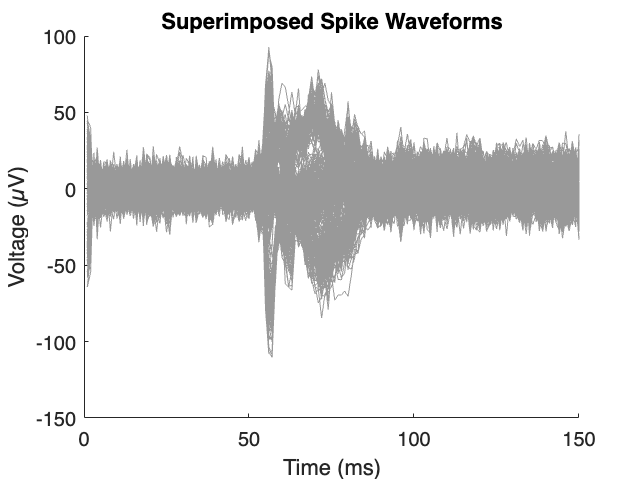

clear all; clc; close all;

addpath('hw2-files/');
load('windowedSpikes.mat'); 

figure(1); hold on; 
%plot(data'); 
plot(data', 'Color', [0.6, 0.6, 0.6]); %Plotting everything
xlabel('Time (ms)');
ylabel('Voltage (µV)');
title('Superimposed Spike Waveforms');
hold off; 

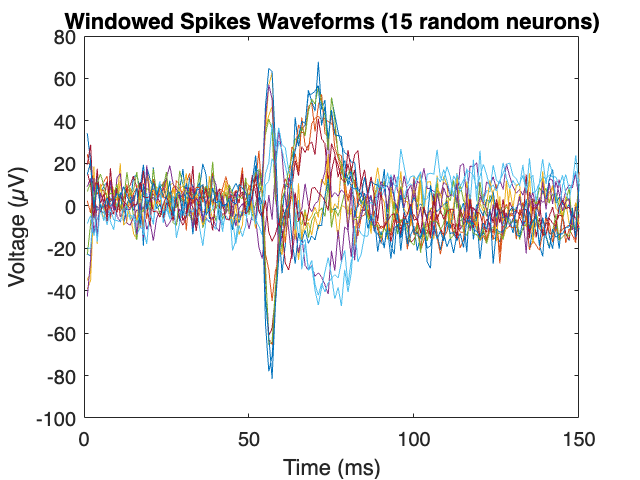


%Ploting just 15 sets of them
figure(2);
plot(data(randi([1, size(data, 1)], 15, 1), :)')
xlabel('Time (ms)')
ylabel('Voltage (µV)')
title('Windowed Spikes Waveforms (15 random neurons)')

From the graph, I think that most waveforms are different and cluttered, especially around 50-100ms. This fact may indicate that these waveforms are not from a same, but different neurons. 

For the patterns of the waveform, they all follow a similar overall pattern, rising and falling around the same time window. There are no noticeable differences in amplotude and shape of the waveforms.

## b)

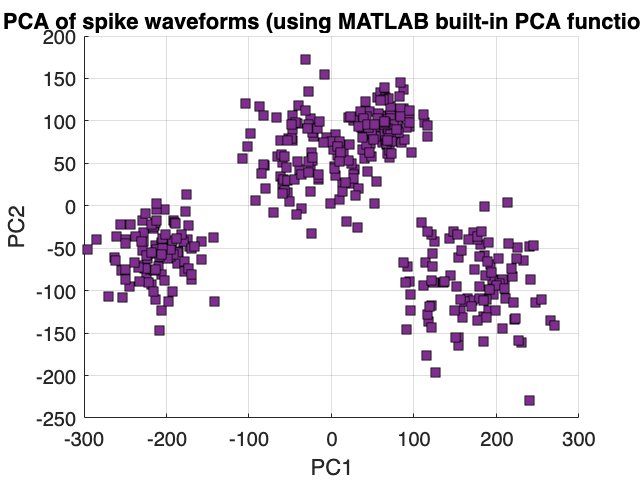

%Using MATLAB built-in PCA function as sanity check
[coeff, score, ~] = pca(data);

% Plot the first two principal components to visualize clustering
figure(3);
scatter(score(:,1), score(:,2), 's', 'filled', ...
    'MarkerEdgeColor','k', 'MarkerFaceColor',[0.4940 0.1840 0.5560])
xlabel('PC1')
ylabel('PC2')
title('PCA of spike waveforms (using MATLAB built-in PCA function)');
grid on;

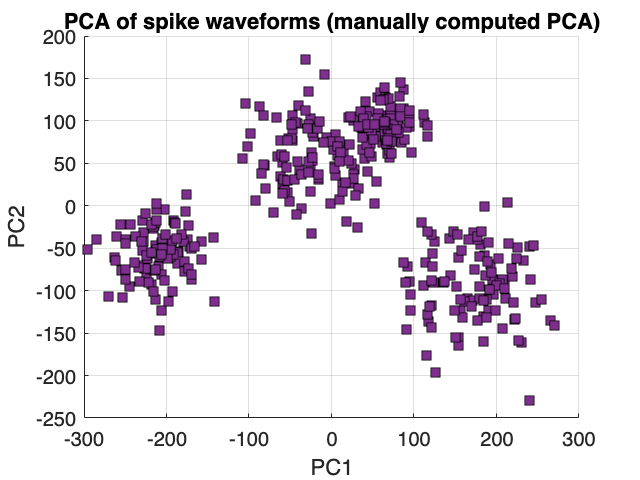


%Performaing PCA with math formulas
data_centered = data - mean(data,1); 
C = data_centered' * data_centered; 
[V,L,Vt] = svd(C);
%disp(L); 
%disp(V);

PC1 = V(:,1); %the largest value in L (the place where the largest value 
% in L is the index)
PC2 = V(:,2); %the second largest value in L

projPC1 = data_centered * PC1;
projPC2 = data_centered * PC2;

% Plot the squared singular values (which correspond to the eigenvalues) 
% Square the singular values to get eigenvalue equivalents
figure(4);
scatter(projPC1, projPC2, 's', 'filled', ...
    'MarkerEdgeColor','k', 'MarkerFaceColor',[0.4940 0.1840 0.5560])
xlabel('PC1')
ylabel('PC2')
title('PCA of spike waveforms (manually computed PCA)');
grid on;

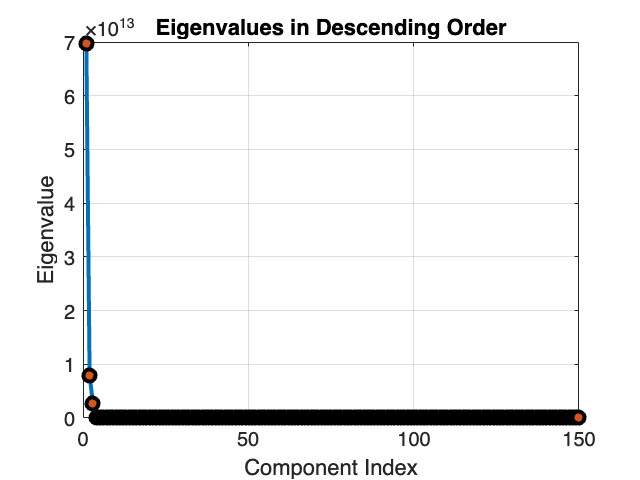



%% Plotting the eigenvalues in descending order
singular_values = diag(L); 
eigenvalues = singular_values .^ 2;
%making descend order
[eigenvalues_sorted, ind] = sort(eigenvalues, 'descend');

figure(5);
plot(eigenvalues_sorted, 'o-', 'LineWidth', 2, 'MarkerSize', 6, ...
    'MarkerEdgeColor', 'k', 'MarkerFaceColor', [0.8500, 0.3250, 0.0980]);
xlabel('Component Index');
ylabel('Eigenvalue');
title('Eigenvalues in Descending Order');
grid on;


disp(eigenvalues_sorted); 

   1.0e+13 *

    6.9670
    0.7974
    0.2672
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0

## c)

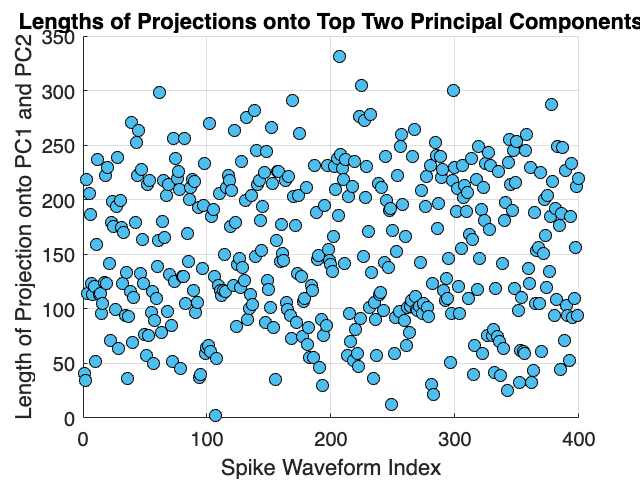

%measuring the length
projection_lengths = sqrt(projPC1.^2 + projPC2.^2);

figure(8);
scatter(1:length(projection_lengths), projection_lengths, 'filled', ...
    'MarkerEdgeColor', 'k', 'MarkerFaceColor', [0.3010 0.7450 0.9330]);

% Label the axes
xlabel('Spike Waveform Index');
ylabel('Length of Projection onto PC1 and PC2');
title('Lengths of Projections onto Top Two Principal Components');
grid on;

From the plotting we can see that there is a wide spread of values of projection length, with the range of 0-350 for y-axis, which is indicating roughly how many spike waveforms can be explained by the top two priciple components. 

In addition, there is no clear clusters and the datapoints are relatively scattered, indicating that the waveforms are not distinctly separable by the top two principal components alone. This can also suggest that either the waveforms maybe potentially coming from the same or very few neurons, or the differencew between neurons' waveforms are not clearly captured by the first two principle components. 

To conclude, combining with the PCA graph, we can deduce that there could be a at least 3 neurons with overlap that is producing those 400 spike waveforms.

## d)

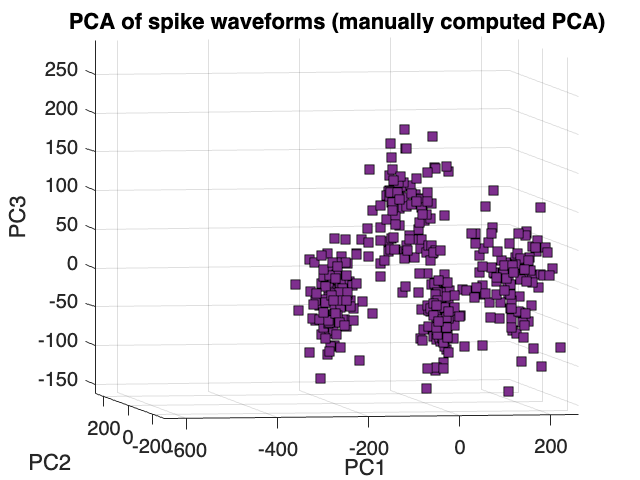

PC3 = V(:,3); %the second largest value in L
projPC3 = data_centered * PC3;
figure(9);
scatter3(projPC1, projPC2, projPC3,'s', 'filled', ...
    'MarkerEdgeColor','k', 'MarkerFaceColor',[0.4940 0.1840 0.5560])
xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
title('PCA of spike waveforms (manually computed PCA)');
grid on;

From visualizing the first three principle components, we can see that there is 4 clusters. Overall, we can deduce that most variances of the 400 spikes can be captured mainly by the first three principle components. Therefore, from this plot we can say that the spikes can be attribute to at least 4 neurons. 